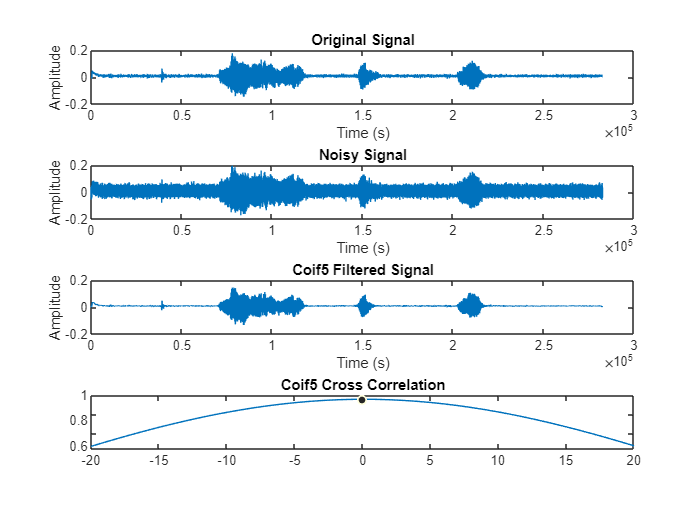

%INPUTTING THE SIGNAL
[x,Fs]=audioread('hellotest.m4a');
y=awgn(x,3,'measured');
audiowrite('noisyHELLOTEST.m4a',y,Fs);

%Choose Wavelet to be Used
sound(xdcoif5_sym2,Fs)

%--WAVELET SPECIFICATIONS--

alpha = 2;
keepapp = 1;

%COIFLET FAMILY
wname1='coif5'; lev1=10;
tobj1 = wpdec(y,lev1,wname1);
det1 = wpcoef(tobj1,2);
sigma1 = median(abs(det1))/0.6745;
thr1 = wpbmpen(tobj1,sigma1,alpha);
xdcoif5 = wpdencmp(tobj1,'s','nobest',thr1,keepapp);

%SYMLET FAMILY
wname2='sym2'; lev2=10;
tobj2 = wpdec(y,lev2,wname2);
det2 = wpcoef(tobj2,2);
sigma2 = median(abs(det2))/0.6745;
thr2 = wpbmpen(tobj2,sigma2,alpha);
xdsym2 = wpdencmp(tobj2,'s','nobest',thr2,keepapp);

%DAUBECHIES FAMILY
wname3='db9'; lev3=10;
tobj3 = wpdec(y,lev3,wname3);
det3 = wpcoef(tobj3,2);
sigma3 = median(abs(det3))/0.6745;
thr3 = wpbmpen(tobj3,sigma3,alpha);
xddb9 = wpdencmp(tobj3,'s','nobest',thr3,keepapp);

% SYMLET FILTERING ON COIFLET-DENOISED SIGNAL
wname4 = 'sym2'; lev4 = 10;
tobj4 = wpdec(xdcoif5, lev4, wname4);
det4 = wpcoef(tobj4, 2);
sigma4 = median(abs(det4))/0.6745;
thr4 = wpbmpen(tobj4, sigma4, alpha);
xdcoif5_sym2 = wpdencmp(tobj4, 's', 'nobest', thr4, keepapp);

% DAUBECHIES FILTERING ON COIFLET-DENOISED SIGNAL
wname5 = 'db9'; lev5 = 10;
tobj5 = wpdec(xdcoif5, lev5, wname5);
det5 = wpcoef(tobj5, 2);
sigma5 = median(abs(det5))/0.6745;
thr5 = wpbmpen(tobj5, sigma5, alpha);
xdcoif5_db9 = wpdencmp(tobj5, 's', 'nobest', thr5, keepapp);

% DAUBECHIES FILTERING ON SYMLET-DENOISED SIGNAL
wname6 = 'db9'; lev6 = 10;
tobj6 = wpdec(xdsym2, lev6, wname6);
det6 = wpcoef(tobj6, 2);
sigma6 = median(abs(det6))/0.6745;
thr6 = wpbmpen(tobj6, sigma6, alpha);
xdsym2_db9 = wpdencmp(tobj6, 's', 'nobest', thr6, keepapp);



nSTDs = 0;
z=-20:1:20;
corrCoif=crosscorr(x,xdcoif5);
corrSym=crosscorr(x,xdsym2);
corrDb=crosscorr(x,xddb9);
corrCoifSym=crosscorr(x,xdcoif5_sym2);
corrCoifDb=crosscorr(x,xdcoif5_db9);
corrSymDb=crosscorr(x,xdsym2_db9);

%COMPARISON OF THE WAVELETS' PERFORMANCES
figure(1)
subplot(4,1,1);plot(x);xlabel('Time (s)');ylabel('Amplitude');title('Original Signal');
subplot(4,1,2);plot(y);xlabel('Time (s)');ylabel('Amplitude');title('Noisy Signal');
subplot(4,1,3);plot(xdcoif5);xlabel('Time (s)');ylabel('Amplitude');title('Coif5 Filtered Signal');
subplot(4,1,4);plot(z,corrCoif);title('Coif5 Cross Correlation');

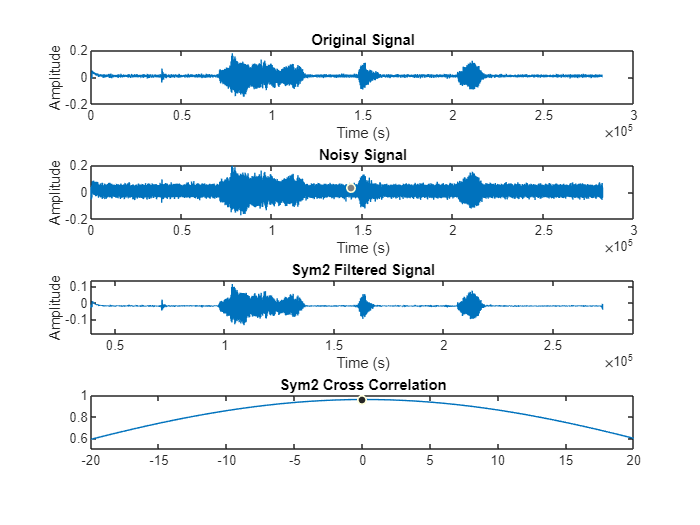


figure(2)
subplot(4,1,1);plot(x);xlabel('Time (s)');ylabel('Amplitude');title('Original Signal');
subplot(4,1,2);plot(y);xlabel('Time (s)');ylabel('Amplitude');title('Noisy Signal');
subplot(4,1,3);plot(xdsym2);xlabel('Time (s)');ylabel('Amplitude');title('Sym2 Filtered Signal');
subplot(4,1,4);plot(z,corrSym);title('Sym2 Cross Correlation');

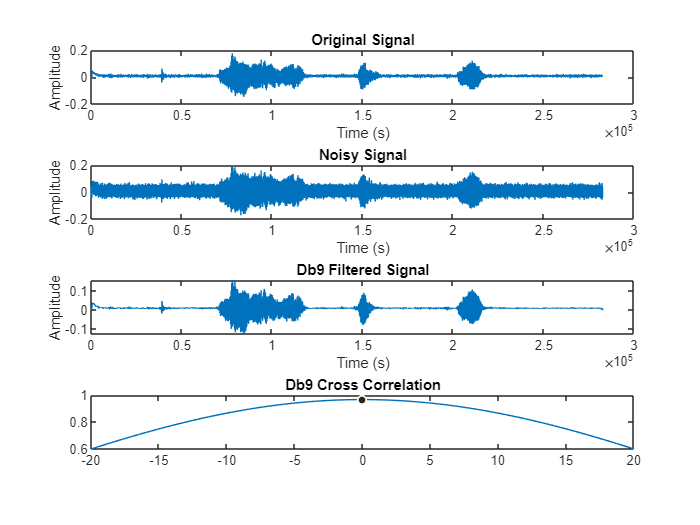


figure(3)
subplot(4,1,1);plot(x);xlabel('Time (s)');ylabel('Amplitude');title('Original Signal');
subplot(4,1,2);plot(y);xlabel('Time (s)');ylabel('Amplitude');title('Noisy Signal');
subplot(4,1,3);plot(xddb9);xlabel('Time (s)');ylabel('Amplitude');title('Db9 Filtered Signal');
subplot(4,1,4);plot(z,corrDb);title('Db9 Cross Correlation');

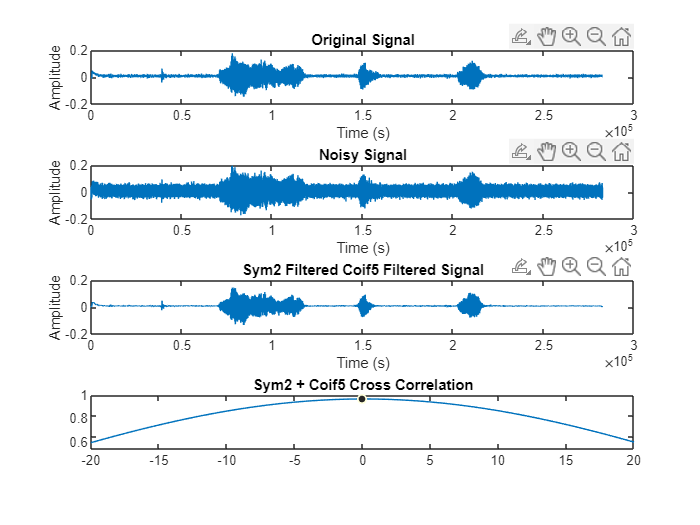


figure(4)
subplot(4,1,1);plot(x);xlabel('Time (s)');ylabel('Amplitude');title('Original Signal');
subplot(4,1,2);plot(y);xlabel('Time (s)');ylabel('Amplitude');title('Noisy Signal');
subplot(4,1,3);plot(xdcoif5_sym2);xlabel('Time (s)');ylabel('Amplitude');title('Sym2 Filtered Coif5 Filtered Signal');
subplot(4,1,4);plot(z,corrCoifSym);title('Sym2 + Coif5 Cross Correlation');

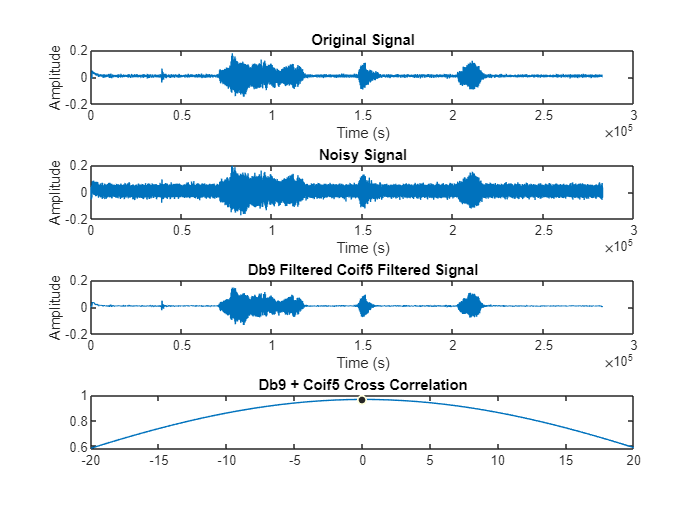


figure(5)
subplot(4,1,1);plot(x);xlabel('Time (s)');ylabel('Amplitude');title('Original Signal');
subplot(4,1,2);plot(y);xlabel('Time (s)');ylabel('Amplitude');title('Noisy Signal');
subplot(4,1,3);plot(xdcoif5_db9);xlabel('Time (s)');ylabel('Amplitude');title('Db9 Filtered Coif5 Filtered Signal');
subplot(4,1,4);plot(z,corrCoifDb);title('Db9 + Coif5 Cross Correlation');

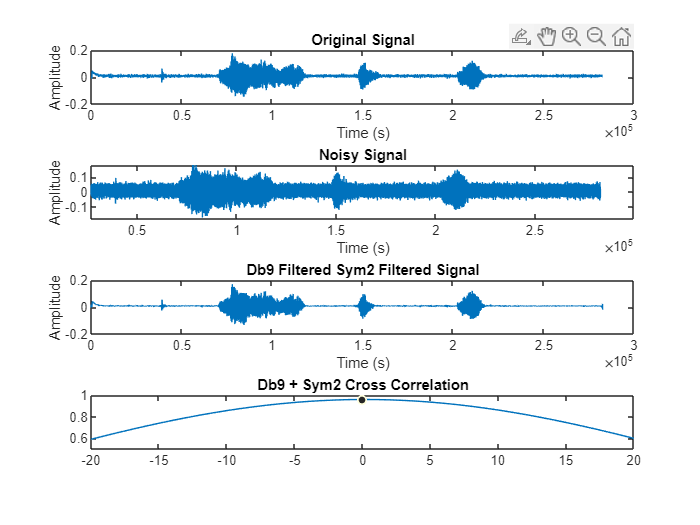


figure(6)
subplot(4,1,1);plot(x);xlabel('Time (s)');ylabel('Amplitude');title('Original Signal');
subplot(4,1,2);plot(y);xlabel('Time (s)');ylabel('Amplitude');title('Noisy Signal');
subplot(4,1,3);plot(xdsym2_db9);xlabel('Time (s)');ylabel('Amplitude');title('Db9 Filtered Sym2 Filtered Signal');
subplot(4,1,4);plot(z,corrSymDb);title('Db9 + Sym2 Cross Correlation');